# **SYST 662 Team 1 Project**

## **Questions**

(Q1) On average, does predictive routing save more than 5% of the trip time to a 95% confidence? 

(Q2) What fraction of trips are re-routed due to road conditions?

## **Notes**

<insert header notes here>

## **Script:**

close all;
clear all; %#ok<CLALL> 

% Declare Answer Variables
Q1_predictive_routing_savings_value = " NOT"; % Replace with "" (empty string) if true
Q2_fraction_of_trips_rereouted_value = 0;

% Load Data Files
load EastCoast.mat
load Supporting_Data_Team_01.mat

% Set Up Simulation
% TODO all code here

## TUTORIAL CODE ONLY - remove after implementing our solution

### Computing times through the graph

The ITS problem requires computing travel times through the road network (graph).  The code below will compute the travel times for five random trips through the baseline graph.

% Define unit conversion
mins_per_hr = 60;
% Select start and stop points for tests
% Randomly selects 5 trips
trips = randi(numnodes(G),5,2); % numnodes(G) returns the # of nodes in the graph

%trips = randi(numnodes(G),numnodes(G),2); % TESTING ALL POSSIBILITIES %
%DONT DO THIS LOL - TAKES A VERY LONG TIME

for k=1:size(trips,1) % size(trips,1) returns the number of rows in the matrix
    % Get the names of the start and end points
    start_name = G.Nodes.Name(trips(k,1)); % Returns a cell array
    end_name   = G.Nodes.Name(trips(k,2)); % Returns a cell array
    fprintf('Trip %d : From [%s] to [%s]\n', ...
        k, start_name{1}, end_name{1});
end

Trip 1 : From [US48/VA55@SR608] to [US22/OH93@+x61]
Trip 2 : From [I-74FutMyr/SC31@WatTowRd] to [US1@GA192]
Trip 3 : From [I-695@1B] to [NC32/US264/NC92]
Trip 4 : From [I-64@114] to [US23/US22/OH56]
Trip 5 : From [I-90(170A)/US42/OH3] to [US220@ForkViewRd]
Trip 6 : From [US250/VA151] to [US76/NC242]
Trip 7 : From [I-97@10] to [I-676@4A]
Trip 8 : From [US460@MonAve] to [US522@+x40]
Trip 9 : From [US48_E/WV93_E] to [US158@+x50]
Trip 10 : From [US119@PA436] to [US1@SC9_W&US52@SC9_W&SC9@US1/52]
Trip 11 : From [US219@LeaMouRd] to [US19@NC1395]
Trip 12 : From [US158@US501/57&US501@US158&NC57@US158_E] to [US70BypGol@+x1]
Trip 13 : From [MD200(16)/US29] to [I-95@+X01|PA]
Trip 14 : From [US224/OH446] to [US50/US301@PinNarRd]
Trip 15 : From [US221@US221BusMar_S&US221BusMar@US221_N&NC226@US221BusMar_S] to [US35_N/WV817_N]
Trip 16 : From [I-76@23&I-77@125&OH8@I-76/77] to [I-695@16]
Trip 17 : From [I-85@57] to [US52Goo@WV/KY&US52@WV/KY&US119Goo@KY/WV&US119Goo@KY/WV]
Trip 18 : From [US50BusBel@OH32_

% Change the graph weights to equal the travel time
% Note the use of vectorization to speed up the computation
G.Edges.Weight = G.Edges.Distance ./ G.Edges.Speed * mins_per_hr;
% Evaluate the trips using the baseline graph
for k=1:size(trips,1)  
    % Find the shortest path from start to end. Indicate all the 
    % Weights are positive to support a faster algorithm
    [path_nominal , t_nominal] = shortestpath(G,trips(k,1),trips(k,2),...
         'method','positive'); 
     
    % Get all the node IDs (numbers) for each node in the path
    node_ids = findnode(G,path_nominal);
    % Get all the edge IDs (numbers) for each edge in the path
    edge_ids = findedge(G, node_ids(1:end-1), node_ids(2:end));
    % Compute the distance of the path by summing the length of each edge
    nominal_distance = sum(G.Edges.Distance( edge_ids ) );
    % Compute the average speed along the path
    average_speed = mean(G.Edges.Speed( edge_ids ) );
    
    fprintf('Trip %2d - %6.2f miles, travel time = %6.2f mins, average speed = %6.2f\n', ...
        k, nominal_distance, t_nominal, average_speed);
end

Trip  1 - 348.37 miles, travel time = 330.38 mins, average speed =  62.62
Trip  2 - 281.44 miles, travel time = 318.30 mins, average speed =  52.97
Trip  3 - 299.35 miles, travel time = 313.07 mins, average speed =  58.09
Trip  4 - 361.98 miles, travel time = 368.61 mins, average speed =  59.39
Trip  5 - 410.33 miles, travel time = 433.18 mins, average speed =  56.70
Trip  6 - 366.13 miles, travel time = 358.31 mins, average speed =  61.94
Trip  7 - 169.21 miles, travel time = 162.46 mins, average speed =  62.55
Trip  8 - 213.45 miles, travel time = 211.58 mins, average speed =  60.62
Trip  9 - 311.41 miles, travel time = 344.16 mins, average speed =  53.40
Trip 10 - 578.89 miles, travel time = 613.50 mins, average speed =  57.18
Trip 11 - 367.02 miles, travel time = 407.53 mins, average speed =  53.64
Trip 12 - 100.01 miles, travel time = 116.13 mins, average speed =  53.11
Trip 13 -   0.00 miles, travel time =    Inf mins, average speed =    NaN
Trip 14 - 360.21 miles, travel time = 

### Generating Random Speeds

The problem calls for generating random speeds.  Assume we know the speeds are Normally distributed with a mean of 50 mph and a standard deviation of 5 mph.  We can create a distribution that generates the specific random variable using the command below. **Note, each team will need to determine the speed distributions using the provided data.**

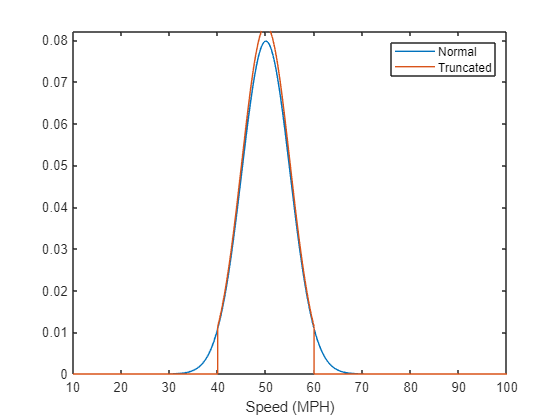

pd = makedist('Normal',50,5);
pd_trunc  = truncate(pd,40, 60);
fplot(@(x) pdf(pd,x),[10 100]);
hold on
fplot(@(x) pdf(pd_trunc,x),[10 100]);
xlabel('Speed (MPH)')
hold off
legend('Normal','Truncated')

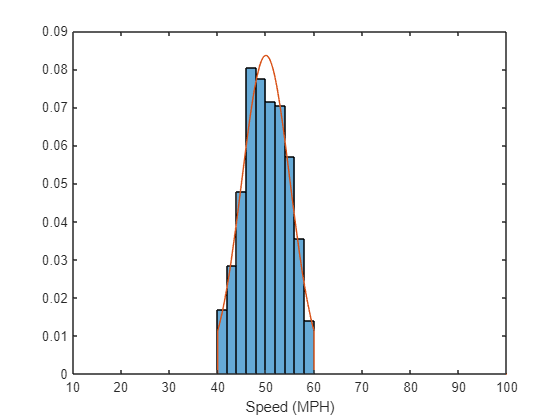

data = random(pd_trunc,[1000,1]);
histogram(data,'Normalization','pdf')
hold on
fplot(@(x) pdf(pd_trunc,x),[10 100]);
xlabel('Speed (MPH)')
hold off

## **Result:**

% Output answers to Q1 and Q2
fprintf('(Q1) On average, does predictive routing save more than 5%% of the trip time to a 95%% confidence?');

(Q1) On average, does predictive routing save more than 5% of the trip time to a 95% confidence?

fprintf('\tQ1: On average, predictive routing does%s save more than 5%% of the trip time to a 95% confidence.', Q1_predictive_routing_savings_value);

	Q1: On average, predictive routing does NOT save more than 5% of the trip time to a 95

fprintf('(Q2) What fraction of trips are re-routed due to road conditions?');

(Q2) What fraction of trips are re-routed due to road conditions?

fprintf('\tQ2: %0.4f%% of trips are re-routed due to road conditions.', Q2_fraction_of_trips_rereouted_value);

	Q2: 0.0000% of trips are re-routed due to road conditions.